%Load the dataset
data = load("visiblehuman.mat");
dataHead = data.head;
dataFresh = data.head_fresh;
dataFrozen = data.head_frozen;
dataMR = data.head_mri;

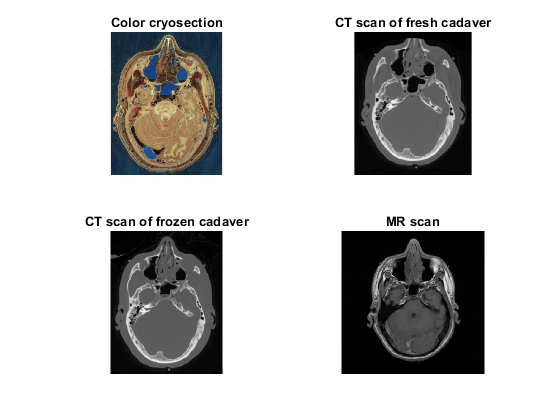

%Visualize the data
figure();
subplot(2, 2, 1);
imshow(dataHead), title("Color cryosection");
subplot(2, 2, 2);
imshow(dataFresh), title("CT scan of fresh cadaver");
subplot(2, 2, 3);
imshow(dataFrozen), title("CT scan of frozen cadaver");
subplot(2, 2, 4);
imshow(dataMR), title("MR scan");

%Load the annotated points
data1 = load("SelPointsG.mat");
data2 = load("SelPointsM.mat");
data3 = load("SelPointsZ.mat");
ColCryo = zeros([10 2 3]);
ColCryo(:, :, 1) = data1.ColCryoPoints;
ColCryo(:, :, 2) = data2.movingPoints;
ColCryo(:, :, 3) = data3.ColCryoPoints;

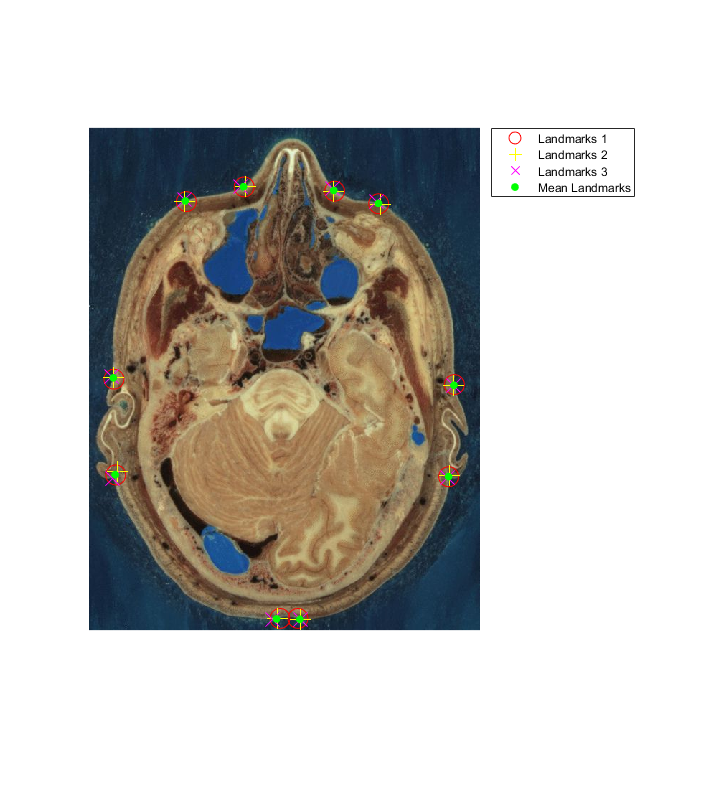


%Visualize the color cryosection annotations
ShowLandmarks(dataHead, ColCryo);


%Calculate the Fiducial localization erro (FLE)
[f, sig] = FeducialLocalizationError(ColCryo)

f =     5.3420   -0.5879
   -0.5879    3.2187


sig = 4.2804

%Add the landmarks to the FreshCT, FrozenCT and MR images
CTFresh = zeros([10 2 3]);
CTFresh(:, :, 1) = data1.CTFreshPoints;
CTFresh(:, :, 2) = data2.fixedPoints;
CTFresh(:, :, 3) = data3.CTFreshPoints;

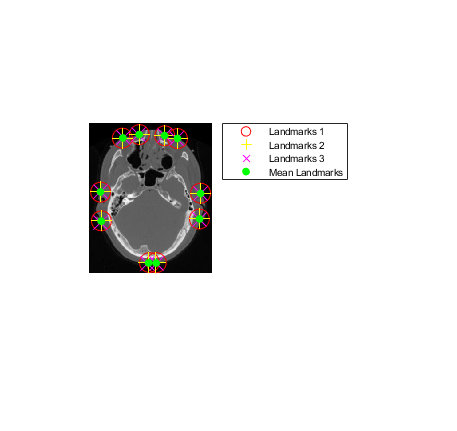

%Visualize the landmarks
ShowLandmarks(dataFresh, CTFresh);